
%% Construct and Plot EMG with Physiologically Accurate Algorithm
fs = 1000;
emg_phys = zeros(1, 100000); % Initialize EMG vector
for i = 1:1000
 % Sum 100 random MUAPTs
 emg_phys = emg_phys + makeTrain(makeMUAP(0.5 + (2-0.5).*rand()));
end
% Lowpass filter EMG
[b, a] = butter(4, [10/(fs/2) 400/(fs/2)]); % Use sampling rate of 1kHz
emg_phys = filter(b, a, emg_phys);
emg_phys = emg_phys(4000:85000);
% Normalize
max = 3 * std(emg_phys);
emg_phys = emg_phys / max;
% Plot EMG and power spectrum
% Time domain plot
t=0:.0005:40.5; % Time vector
subplot(3, 1, 1); plot(t, emg_phys);
xlabel('Time (s)'); xlim([0 40]);
ylabel('Amplitude'); ylim([-2 2]);
title('Physiologic EMG Signal Simulation');
% Power spectral density plot
subplot(3,1,2);
periodogram(emg_phys);
title('Physiologic EMG Power Density Spectrum');
% Distribution plot
subplot(3,1,3);
hist(emg_phys, 100); 
wxlim([-2 2]);
xlabel('Value');
ylabel('Samples');
title('Physiologic EMG Distribution');
skew2 = skewness(emg_phys);
fprintf('Skewness in Physiological EMG: %.4f\n',skew2);

Skewness in Physiological EMG: 0.0258


kurt2 = kurtosis(emg_phys);
fprintf('Kurtosis in Physiological EMG: %.4f\n',kurt2);

Kurtosis in Physiological EMG: 3.5558


median2 = median(emg_phys);
fprintf('Median in Physiological EMG: %.4f\n',median2);

Median in Physiological EMG: -0.0003


mean2 = mean(emg_phys);
fprintf('Mean in Physiological EMG: %.4f\n',mean2)

Mean in Physiological EMG: 0.0000


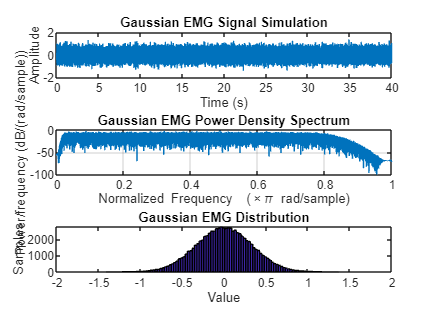

%% Construct and Plot EMG from Gaussian distribution
fs = 1000;
emg_gauss = randn(1, 81001); % Length chosen to match physiologic
% Lowpass filter EMG
[b, a] = butter(4, [10/(fs/2) 400/(fs/2)]); % Use sampling rate of 1kHz
emg_gauss = filter(b, a, emg_gauss);
% Normalize
max = 3 * std(emg_gauss);
emg_gauss = emg_gauss / max;
% Plot EMG and power spectrum
% Time domain plot
t=0:.0005:40.5; % Time vector
figure(2);
subplot(3, 1, 1), plot(t, emg_gauss);
xlabel('Time (s)'); xlim([0 40]);
ylabel('Amplitude'); ylim([-2 2]);
title('Gaussian EMG Signal Simulation');
% Power spectral density plot
subplot(3,1,2), periodogram(emg_gauss)
title('Gaussian EMG Power Density Spectrum');
% Distribution plot
subplot(3,1,3),hist(emg_gauss, 100);
xlabel('Value'); xlim([-2 2]);
ylabel('Samples');
title('Gaussian EMG Distribution');

skew1 = skewness(emg_gauss);
fprintf('Skewness in Gaussian: %.4f\n',skew1);

Skewness in Gaussian: -0.0046


kurt1 = kurtosis(emg_gauss);
fprintf('Kurtosis in Gaussian: %.4f\n',kurt1);

Kurtosis in Gaussian: 2.9885


median1 = median(emg_gauss);
fprintf('Median in Gaussian: %.4f\n',median1);

Median in Gaussian: -0.0000


mean1 = mean(emg_gauss);
fprintf('Mean in Gaussian: %.4f\n',mean1) 

Mean in Gaussian: 0.0000


function[MUAP]=makeMUAP(distance)
% Note: distance parameter specifies the distance of the fiber of interest
% below the skin (and recording site)
%% Construct vector to represent single muscle fiber
fiberLength=500;
MUAP1=zeros(1, fiberLength);
%% Construct MUAP
% Simulate action potetial propagating down muscle fiber
for i=1:fiberLength
 % Calculate signal strength at recording site by calculating distance
 % Assumes that signal strength is proportional to distance
 MUAP1(i)=1/sqrt(distance^2+(fiberLength/2-i)^2);
end
MUAP1=[zeros(1,1000) MUAP1 zeros(1,1000)]; % Pad with zeros
% Add inverted peak with specified offset
% Accounts for the effect of bipolar differential recording electrodes
MUAP2=-[zeros(1,150) MUAP1];
MUAP1=[MUAP1 zeros(1,150)];
MUAP=MUAP1+MUAP2;
end
function[MUAPT]=makeTrain(MUAP)
%% Initializes MUAPT with a random number of leading zeros
MUAPT=[zeros(1, randi([2000 7000])) MUAP];
for i=1:10
 % Add MUAPs to train at random intervals
 MUAPT=[MUAPT zeros(1, randi([2000 7000])) MUAP];
end
MUAPT=[MUAPT zeros(1, 100000-length(MUAPT))];
end
% 1.make muap funciton with distance as its parameter 
% take fiber length as 500 au
% 2. Do zero padding
% 3. Generate inverted muap copy
% 4. Add both the copy 
% 
% Under muap function .......no.1 function
% 
% 5. Generated muap train function - no 2 function 
% 
% Main program:
% 6. Take sampling frequency of 1000 hz
% 7. Take 100 no. of muap train and add them 
% 8. Use filtering (butterworth [10-400hz]
% 9. Normalize the filtered signal
% 10. Plot the physiological signal its PSD, its distribution
% 11. Generate gaussian EMG with sampling frequency 1000 Hz
% with repetation from step (6-10)
% 
% 12. Finally, find the mean, median, Skewness, Kurtosis of both physilogic 
% and gaussian EMG.
